# AERO 423 - HW3 

## Problem 1 - Orbital Elements

**PART A**

[h,i,OMEGA,e,omega,theta] from [r,v] specified in geocentric equatorial frame. Is ISS in retrograde orbit? Is the satellite flying towards or away from perigee? 

Period of the orbit?

What are the position and velocity vectors of the satellite in the perifocal frame precisely 24 hours later.


r = [-10063.829, -473.07, -12487.599];
v = [-0.359, -4.950, 0.475];

[h,i,OMEGA,e,omega,phi] = cartesian2OrbitElements( r,  v);

v_r = 0.001434 > 0: satellite is flying away from perigee 
Not in retrograde orbit



mu = 398600;

r_p = h^2 / mu * ( 1/(1+e) );
r_a = h^2 / mu * ( 1/(1-e) );
a = .5 * (r_p + r_a); 
T = 2*pi /sqrt(mu) * a^(1.5); 

fprintf("a = %f km,\n e = %f,\n i = %f deg,\n OMEGA = %f deg,\n ..." + ...
    "omega = %f deg,\n phi=%f\n deg", a,e,i*180/pi,OMEGA*180/pi,omega*180/pi,phi*180/pi)

a = 16054.449583 km,
 e = 0.000651,
 i = 51.639276 deg,
 OMEGA = 261.507519 deg,
 ...omega = 250.751280 deg,
 phi=26.244051
 deg


fprintf( 'Orbital period is: %f hr\n', T/(3600) );

Orbital period is: 5.623437 hr


**PART B**

[r, v] in perifocal and geocentric equatorial frames. MU = 398600. 

h = 80e3; 
e = 0.00083;
i = deg2rad(51.2); 
OMEGA = deg2rad(250); 
omega = deg2rad(240); 
theta = deg2rad(15); 
[r,v] = orbit2GeocentricCartesian(h,e,i,OMEGA,omega,theta);

fprintf('r = \r'); fprintf('%f\r', r);

r = 
-7704.494787
7223.013956
-12077.144108


fprintf('v = \r'); fprintf('%f\r', v);

v = 
-2.407807
-4.249037
-1.006619


## Problem 2

Lecture: 423-07, pg. 6

Higher transfer orbit example problem in the lecture

R = 7000;  
k = 10; 
beta = 270*pi/180; 
mu = 398600;


T0 = 2*pi*sqrt(R^3/mu);
n0 = 2*pi/T0;

T1 = T0 + ( 2*pi - beta ) / ( k*n0 );

a = ( mu * ( T1/(2*pi) )^2 )^(1/3);

va = sqrt( 2*mu/R - mu/a ); 
vb = sqrt( mu/R ); 
dV = 2*( va-vb )

dV = 0.1227

Lower transfer orbit HW #3 question: 

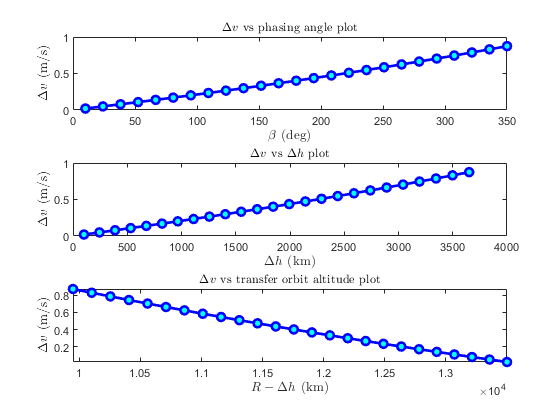

R = 13600;  
k = 5; 
% beta = 270*pi/180; 
mu = 398600;

T0 = 2*pi*sqrt(R^3/mu);
n0 = 2*pi/T0;

samples = 25; 
beta = linspace(10, 350, samples);
dV = zeros(samples, 1); 
dH = dV;

for ii = 1:samples
    T1 = T0 - deg2rad( beta(ii) ) / ( k*n0 );
    a = ( mu * ( T1/(2*pi) )^2 )^(1/3);
    dH(ii) = 2*(R - a);
    
    va = sqrt( mu/R * (2 * (R - dH(ii) ) / (2*R-dH(ii)) ) );
%     va = sqrt( 2*mu/R - mu/a ); 
    vb = sqrt( mu/R ); 
    dV(ii) = 2* ( vb-va );
end

figure; 
subplot(3,1,1)
plot(beta, dV, '-ob','LineWidth',2, 'MarkerFaceColor','c');
xlabel("$\beta$ (deg)", "Interpreter","latex", "FontSize",10);
ylabel("$\Delta v$ (m/s)","Interpreter","latex", "FontSize",10);
title("$\Delta v$ vs phasing angle plot" , "Interpreter","latex", "FontSize",10);

subplot(3,1,2)
plot(dH, dV, '-ob','LineWidth',2, 'MarkerFaceColor','c');
xlabel("$\Delta h$ (km)", "Interpreter","latex", "FontSize",10);
ylabel("$\Delta v$ (m/s)","Interpreter","latex", "FontSize",10);
title("$\Delta v$ vs $\Delta h$ plot" , "Interpreter","latex", "FontSize",10);

subplot(3,1,3)
plot(R-dH, dV, '-ob','LineWidth',2, 'MarkerFaceColor','c');
xlabel("$R-\Delta h$ (km)", "Interpreter","latex", "FontSize",10);
ylabel("$\Delta v$ (m/s)","Interpreter","latex", "FontSize",10);
title("$\Delta v$ vs transfer orbit altitude plot" , "Interpreter","latex", "FontSize",10);

axis tight

## Problem 3a

inclination = 98.43;
latitude    = 28.5; 
az = launchAzimuth( inclination, latitude )    

az = -9.6028


if az < 0
    az = 180 - az;  
end

fprintf("Launch Azimuth A = %f\n", az); 

Launch Azimuth A = 189.602761


## Problem 3b

   T = 100*60; % orbit period in seconds
   mu = 398600;
   
   % descending node
   t_des = T/4; 
   
   % ascending node
   t_asc = 3*T/4; 
   
   fprintf("Descending node at t_des = %f and ascending node at t_asc = %f\n", t_des, t_asc);

Descending node at t_des = 1500.000000 and ascending node at t_asc = 4500.000000


   
   R = ( ( T / (2*pi) )^2 * mu )^(1/3)

R = 7.1366e+03

   v = sqrt( mu/R )

v = 7.4735

   
   % Delta v
   delta_i = 28.5 - 28;
   dV = 2*v*sind(delta_i/2)

dV = 0.0652

## Problem 4

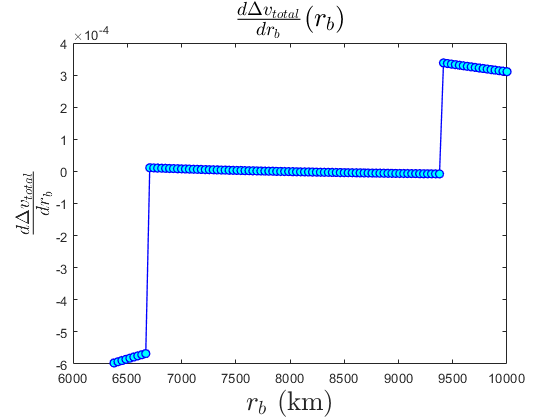

% Bisection method

% bounds

a = 6378; 
b = 10000; 

syms r_b real
dv_total_func = dV_total(r_b);   % look out for delta_v_total function below

% symbolic differentiation of delta_v_total wrt rb 
DV_total = diff(dv_total_func, r_b);  
rb_eqn = DV_total == 0; 

rb_root = vpasolve(rb_eqn, r_b); % nonlinear root solver - my reference for bisection


% Plotting the obtained delta_v functions for find their nature
rb = linspace(a, b, 100); 
dv_drb = zeros(100,1); 
dv_total_func_vals = zeros(100,1); 

for ii = 1:100
    dv_drb(ii) = subs(DV_total, r_b, rb(ii));
    dv_total_func_vals(ii) = subs(dv_total_func, r_b, rb(ii)); 
end


figure 
plot(rb, dv_drb, '-ob', 'MarkerFaceColor','c', 'LineWidth', 1); 
ylabel('$\frac{d \Delta v_{total}}{dr_b}$','Interpreter', 'Latex', 'FontSize',20); 
xlabel('$r_b$ (km)','Interpreter', 'latex', 'FontSize',20); 
title('$\frac{d \Delta v_{total}}{dr_b} (r_b)$','Interpreter', 'latex', 'FontSize',20);

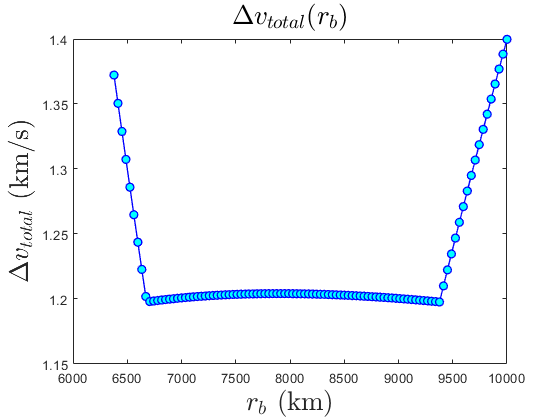


figure 
plot(rb, dv_total_func_vals, '-ob','MarkerFaceColor','c', 'LineWidth',1);
ylabel('$\Delta v_{total}$ (km/s)','Interpreter', 'Latex', 'FontSize',20); 
xlabel('$r_b$ (km)','Interpreter', 'latex', 'FontSize',20); 
title('$\Delta v_{total}(r_b)$','Interpreter', 'latex', 'FontSize',20);



 
% Bisection method initiation   
iter = 0; tol = 1e-6; max_iter = 1000;

while (b - a) / 2 > tol && iter < max_iter
    
    rb = (a + b) / 2; 
    dv_total_val = subs(DV_total, r_b, rb); 
    
    if dv_total_val == 0  
       break;
    elseif dv_total_val < 0
       b = rb;       
    else
       a = rb;       
    end
       iter = iter + 1;  
end
    
val = (a + b) / 2;  % root for r_b
fprintf('Root for r_b is found after %d iterations: %f\n', iter, val);

Root for r_b is found after 31 iterations: 7894.772060


fprintf('Delta v total = %f\n', dV_total(val)); 

Delta v total = 1.204150


## Problem 5

mu_sun = 132.71 * 1e9; 
R_saturn = 1.433 * 1e9; 
R_mars = 227.9 * 1e6; 

T_mars = 2*pi*sqrt(R_mars^3/mu_sun); 
T_saturn = 2*pi*sqrt(R_saturn^3/mu_sun);
n_mars = 2*pi / T_mars; 
n_saturn = 2*pi / T_saturn; 

% semi-major axis
a_transfer = (R_saturn + R_mars)/2; 

t_transfer = pi * sqrt(a_transfer^3 / mu_sun);

% Part 1: Departure angle - Multirevolution problem
% Mars completes n revolutions in the transfer time 
n_revs = n_mars * t_transfer; 

theta_depature = pi - mod(n_revs, 1); 
fprintf("At departure Saturn to Mars must be %f (rad) or %f deg\n", ...
    theta_depature, theta_depature*180/pi);

At departure Saturn to Mars must be 2.288967 (rad) or 131.148169 deg




% Part 2: Delta V
V_saturn = sqrt( mu_sun / R_saturn );
V_departure = sqrt(2*mu_sun)*sqrt(R_mars / (R_saturn * (R_mars + R_saturn) ));

% Required Delta_v at departure
dV_departure =  V_saturn - V_departure % saturn is faster

dV_departure = 4.5821


% another approach 
% dV_departure = sqrt(mu_sun / R_saturn) * ( sqrt(2*R_mars/(R_mars + R_saturn) ) - 1 )

V_mars = sqrt( mu_sun / R_mars );
V_arrival = sqrt(2*mu_sun)*sqrt( R_saturn / ( R_mars * (R_mars + R_saturn) ) ) 

V_arrival = 31.6990


dV_arrival = V_arrival - V_mars ;

% dV_arrival = sqrt(mu_sun / R_mars) * ( sqrt(2*R_saturn/(R_mars + R_saturn) ) - 1 )

fprintf('Round trip delta v is %f km/s\n', 2*(dV_departure + dV_arrival));

Round trip delta v is 24.299754 km/s




% Part 3: Waiting time in Mars for starting Hohman Transfer back to Saturn

% t_wait = 2 * ( (2*pi - n_saturn*t_transfer) / (n_mars - n_saturn) );
t_wait = 2 * ( ( n_saturn*t_transfer) / (n_mars - n_saturn) );
fprintf("Waiting time in Mars before transfering back to Saturn is %f years or %f days or %d s", ...
     t_wait/(24*60*60*365), t_wait/(24*60*60), t_wait);

Waiting time in Mars before transfering back to Saturn is 0.886330 years or 323.510423 days or 2.795130e+07 s

pf = pi - n_saturn*t_transfer; 

t_wait = -2*pf / (n_mars - n_saturn) + 2*pi*1 / (n_mars - n_saturn)

t_wait = 2.7951e+07

t_wait = t_wait / (24*3600)

t_wait = 323.5104

# Functions

function dV_t = dV_total(rb) 
 
% Problem 4: Bielliptic transfer - delta_v as a function of rb
   mu = 398600.44;
   Re = 6378.135; 
   ra = Re + 300; 
   rc = Re + 3000; 
   
   va = sqrt( mu/ra ); 
   vc = sqrt( mu/rc );
   
   va1 = sqrt( 2*mu*rb / ( ra*(ra+rb)) ); 
   vb1 = sqrt (2*mu*ra / (rb*(ra+rb)) );
   
   vb2 = sqrt( 2*mu*rc / (rb*(rb+rc)) );
   vc2 = sqrt( 2*mu*rb / (rc*(rb+rc)) );
   
   dVa = va1 - va; 
   dVb = vb2 - vb1;
   dVc = vc2 - vc; 
   
   dV_t = abs(dVa) + abs(dVb) + abs(dVc); 
   
end

function A = launchAzimuth(inclination, latitude)
    % all in degrees
    
    A = asin( cos(inclination * pi/180) / cos(latitude * pi/180) );
    A = A * 180/pi;

end


function [h_mag,i,OMEGA,e_mag,omega,theta] = cartesian2OrbitElements(r, v)

% r,v are 3x1 vectors
 r = reshape(r, [3,1]); 
 v = reshape(v, [3,1]); 
 
 r_mag = norm(r); 
 v_mag = norm(v); 
 
 v_r = v' * r / r_mag; 
 
 if (v_r > 0)
     fprintf('v_r = %f > 0: satellite is flying away from perigee \n', v_r); 
 end
 
 % step 4
 h = cross(r,v); 
 
 %step 5
 h_mag = norm(h); 
 
 %step 6
 i = acos( h(3)/h_mag );
 if(i > pi/2)
 fprintf("i = %f deg > 90 deg: retrograde orbit\n", rad2deg(i));
 else
     fprintf("Not in retrograde orbit\n");
 end
 
 K = [0 0 1]'; 
 N = cross(K,h); 
 N_mag = norm(N); 
 
 % 9 RAAN
 OMEGA = acos( N(1) / N_mag ); 
 
 if(N(2) < 0 )
     OMEGA = 2*pi - OMEGA;
 end
 
 % 10 Eccentricity vector
 mu = 398600; 
 e = 1/mu * [ (v_mag^2 - mu / r_mag) * r - r_mag * v_r * v ];
 e_mag = norm(e);

 % 11
 omega = acos( N' * e / ( norm(N)*norm(e) ) );
 
 if (e(3) < 0)
     omega = 2*pi - omega;
 end
 
 % 13 True anomaly
 theta = acos( e' * r / ( e_mag * r_mag ) ); 
 
 if (v_r < 0)
     theta = 2*pi - theta;
 end
end

function [r_X,v_X] = orbit2GeocentricCartesian(h, e, i, OMEGA, omega, theta)

% state vectors r and v in geocentric equatorial frame: Page 175
    
    mu = 398600;  
    
    p = h^2 / mu; % semi-latus rectum
    
    r_x = p / (1 + e * cos(theta) ) * [cos(theta) sin(theta) 0]'; 
    
    v_x = mu / h * [-sin(theta) e+cos(theta) 0]' ;
    
    QXx = C3(omega) * C1(i) * C3(OMEGA);
    QxX = QXx';  
    
    r_X = QxX * r_x; 
    v_X = QxX * v_x; 
    
end
function R = C3(angle)

R = [ cos(angle) sin(angle) 0; 
      -sin(angle) cos(angle) 0;
    0 0 1  ] ; 
end
function R = C1(angle)
    R = [1 0 0; 
        0 cos(angle) sin(angle); 
        0 -sin(angle) cos(angle)]; 
end